# Industrial Engineering

#### Introduzione

Prendiamo la funzione $f(x) = 40x^{3/2} - 875x + 35 \,000$ e cerchiamo delle funzioni che abbiano come punto fisso $f(\alpha)$.

Ottengo (ponendo $c = 35 \, 000$):

- $g_1(x) = x - \frac{40x^{3/2} - 875x + c}{60\sqrt x - 875}$ (Metodo di Newton)

- $g_2(x) = - \frac{c}{40 \sqrt x - 875}$ (Spostando la $c$ a sinistra, mettendo in evidenza la $x$ e dividendo da entrambi i lati ciò che c'è dentro la parentesi)

- $g_3(x) = \frac{40 x^{3/2} + c}{875}$ (Spostando il termine con la $x$ a sinistra e dividendo entrambi i lati per il suo coefficiente)

Questo funzioni sono funzioni continue. Verifichiamo che in un certo intervallo $[a,b]$ il codominio di queste funzioni sia contenuto nel dominio. 

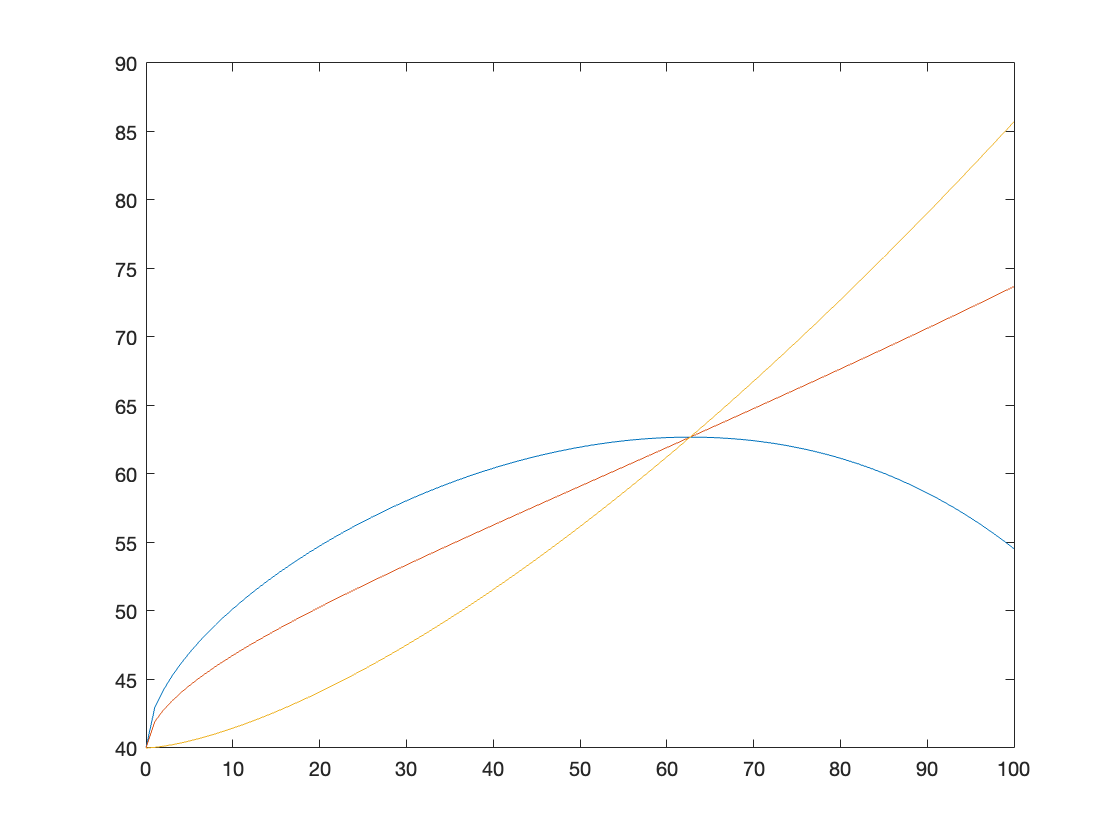

x = 0 : 100;

g1 = @(x) x - (40*x.^(3/2) - 875*x + 35000)./(60*x.^(1/2) - 875);
g2 = @(x) -35000./(40*x.^(1/2) - 875);
g3 = @(x) (40*x.^(3/2) + 35000)/875;

y1 = g1(x); y2 = g2(x); y3 = g3(x);

plot(x, y1, x, y2, x, y3)

Eseguendo un rapido plot notiamo che Newton ha un massimo intorno a $60$, mentre le altre due sono monotone, quindi basterà verificare che gli estremi del codominio siano contenuti nel dominio.

a = 0; b = 100;

if min(y1) >= a && max(y1) <= b
    disp('La funzione g1 ha codominio compreso nel dominio')
else
    disp('La funzione g1 non ha codominio compreso nel dominio')
end

La funzione g1 ha codominio compreso nel dominio



if min(y2) >= a && max(y3) <= b
    disp('La funzione g2 ha codominio compreso nel dominio')
else
    disp('La funzione g2 non ha codominio compreso nel dominio')
end

La funzione g2 ha codominio compreso nel dominio



if min(y3) >= a && max(y3) <= b
    disp('La funzione g3 ha codominio compreso nel dominio')
else
    disp('La funzione g3 non ha codominio compreso nel dominio')
end

La funzione g3 ha codominio compreso nel dominio


Quindi abbiamo che tutte le funzioni rispettano la condizione sufficiente per l'esistenza di un punto fisso. Verifichiamo anche che questo punto fisso sia unico, quindi calcoliamo le derivate e verifichiamo che nell'intervallo $(a,b)$ siano minori di un certo $m$ compreso tra $0$ ed $1$. Per semplicità, maggioriamo la nostra $m$ e poniamola ad $1$ per ora.

- 
$$g_1'(x) = \frac{6(8x^{3/2} - 175 + 7000)}{(12 \sqrt x - 175)^2 \sqrt x}$$


- 
$$g'_2(x) = \frac{28 \, 000}{(8\sqrt x - 175)^2\sqrt x}$$


- 
$$g_3'(x) = \frac{12 \sqrt x}{175}$$


%x = 0 : 100;
x = 10 : 100;
dg1 = @(x) 6 * ((8*x.^(3/2) - 175*x + 7000) ./ ((12*x.^(1/2) - 175).^2 .* x.^(1/2)));
dg2 = @(x) 28000 ./ ((8*x.^(1/2) - 175).^2 .* x.^(1/2));
dg3 = @(x) (12*x.^(1/2))/175;

m1 = -1; m2 = -1; m3 = -1;

dy1 = dg1(x);
dy2 = dg2(x);
dy3 = dg3(x);

m1 = max(abs(min(dy1)), abs(abs(max(dy1))));
m2 = max(abs(min(dy2)), abs(abs(max(dy2))));
m3 = max(abs(min(dy3)), abs(abs(max(dy3))));

if abs(max(dy1)) >= 1 || abs(min(dy1)) >= 1
   disp('La derivata di g2 è maggiore di m')
end

if abs(max(dy2)) >= 1 || abs(min(dy2)) >= 1
   disp('La derivata di g2 è maggiore di m')
end

if abs(max(dy3)) >= 1 || abs(min(dy3)) >= 1
   disp('La derivata di g3 è maggiore di m')
end

Notiamo che entrambe le derivate assumono un valore maggiore uguale di 1. Eseguiamo un rapido plot e verifichiamo dove potrebbe essere il problema.

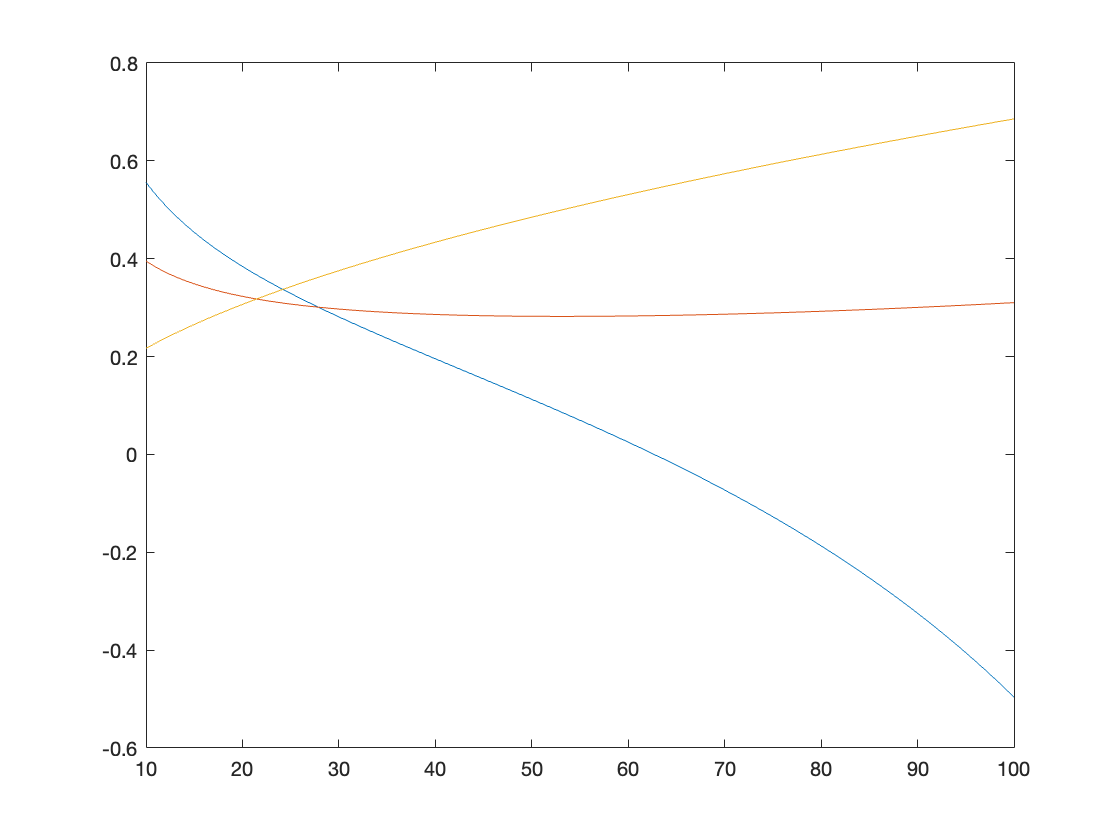

plot(x, dy1, x, dy2, x, dy3)

m1

m1 = 0.5559

m2

m2 = 0.3951

m3 

m3 = 0.6857

Riproviamo quindi ora ponendo l'intervallo $[10, 100]$. Inoltre ho anche trovato lo specifico $m$ per entrambe le funzioni.

#### Ch. 1

Perfetto adesso ci troviamo in un intervallo $[a, b]$ con $a = 10$ e $b = 100$ in cui le funzioni rispettano le seguenti condizioni:

- Le funzioni $g_i$ sono continue nell'intervallo $(a, b)$, ed il loro codominio è contenuto nel dominio;

- Le funzioni $g_i$ ammettono derivata, ed essa è continua ed in valore assoluto minore di $1$per ogni punto nell'intervallo $(a, b)$.

Quindi otteniamo che il punto fisso esiste per queste due funzioni ed inoltre esso è unico.

Per il **teorema di convergenza globale** abbiamo che se poniamo la successione $x_{k+1} = g_i(x_k)$ essa convergerà all'unico punto fisso presente nell'intervallo $(a, b)$. 

clear x;
tol = 1e-20;
Kmax = 300;
x0 = 10.1;


g1 = @(x) x - (40*x^(3/2) - 875*x + 35000)/(60*x^(1/2) - 875);
g2 = @(x) -35000/(40*x^(1/2) - 875);
g3 = @(x) (40*x^(3/2) + 35000)/875;

% //--------------------//
% Funzione g1

x = x0; i = 1; e = 1;
while i < Kmax && e > tol
    px = x;
    x = g1(x);
    
    e = abs(px - x);
    i = i+1;
end
fprintf('La prima funzione impiega %d iterazioni per trovare il valore %f', i, x)

La prima funzione impiega 7 iterazioni per trovare il valore 62.691697


% //--------------------//
% Funzione g2

y = x0; i = 1; e = 1;
while i < Kmax && e > tol
    py = y;
    y = g2(y);
    
    e = abs(py - y);
    i = i+1;
end
fprintf('La seconda funzione impiega %d iterazioni per trovare il valore %f', i, y)

La seconda funzione impiega 24 iterazioni per trovare il valore 62.691697


% //--------------------//
% Funzione g3

z = x0; i = 1; e = 1;
while i < Kmax && e > tol
    pz = z;
    z = g3(z);
    
    e = abs(pz - z);
    i = i+1;
end
fprintf('La terza funzione impiega %d iterazioni per trovare il valore %f', i, z)

La terza funzione impiega 45 iterazioni per trovare il valore 62.691697

Otteniamo che la successione che converge per prima è quella generata con il metodo di Newton, che è seguita da $g_2$ e poi $g_3$. 

Calcoliamo ora il valore della derivata nel punto $\alpha$ per ogniuna di queste funzioni.

% Diamo un occhiata al valore della derivata nel punto alpha

% g1
y1 = 6*(8*x^(3/2) -175*x + 7000)/((12*x^(1/2) - 175)^2 * x^(1/2));

% g2
y2 = 28000/((8*y^(1/2) - 175)^2 * y^(1/2));

% g3
y3 = (12*z^(1/2))/175;

fprintf('La derivata di g1 nel punto alpha è uguale a %e', y1);

La derivata di g1 nel punto alpha è uguale a -1.077247e-16

fprintf('La derivata di g2 nel punto alpha è uguale a %e', y2);

La derivata di g2 nel punto alpha è uguale a 2.836462e-01

fprintf('La derivata di g3 nel punto alpha è uguale a %e', y3);

La derivata di g3 nel punto alpha è uguale a 5.429355e-01

...

#### Ch. 2

E' possibile trovare altre funzioni con punti fissi per risolvere più velocemente questa specifica equazione?

tol = 0.0001;
Kmax = 1000;
g = @(x) (40*x.^(3/2) + (874 - i)*x + 35000) / i;
iter = zeros([874, 1]);

for i=1 : 874
    k = 1; e = 100; xk1 = 10.1;
    while k < Kmax && e > tol
        xk = xk1;                                                                                                                                                                                          
        xk1 = g(xk);
        
        e = abs(xk1 - xk);
        k = k+1;
    end
    iter(i) = k;
end
min(iter)

ans = 22

max(iter)

ans = 22

Il numero di iterazioni è sempre lo stesso.

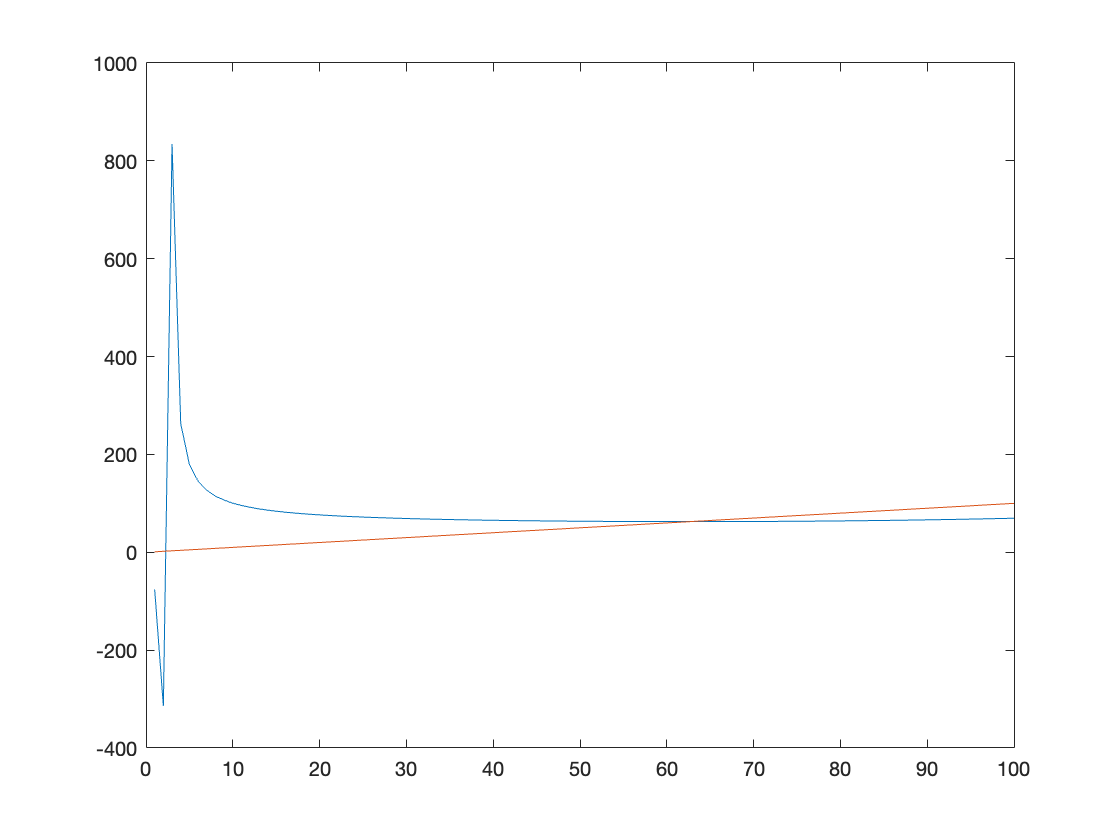

x = 1:100;
Kmax = 1000;
tol = 0.0000001;
f = @(x) (40*x.^(3/2) - 875*x + 35000) ;
phi = @(x) (40*x.^(3/2) - 875*x + 35000) ./  (60 * x.^(1/2) - 875); 
dphi = @(x) 1 - ((30 .* (40.*x.^(3/2) - 875.*x + 35000)) ./ ((60*x.^(1/2) - 875).^2 .* x.^(1/2)));

g = @(x) x - phi(x)./dphi(x);

plot(x, g(x), x, x)


x = 10.1; i = 1; e = 1;
while i < Kmax && e > tol
    px = x
    x = g(x);
    
    e = abs(px - x);
    i = i+1;
end

px = 10.1000

px = 99.8794

px = 69.5662

px = 62.9147

px = 62.6919

px = 62.6917

i

i = 7

Un iterazione in più di Newton usando la funzione:

- 
$$\phi(x) = \frac{f(x)}{f'(x)}$$


- 
$$g(x) = x - \frac{\phi(x)}{\phi'(x)}$$
